Basic step response

% Define numerator and denominator of G(s)
omega_n = 10;
zeta = 0.25;
t = 0:0.01:2.5;  % Time vector from 0 to 2.5 seconds with 0.01s step

num = omega_n^2

num = 100

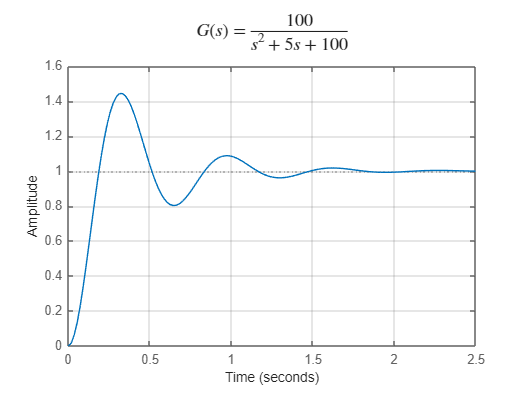

den = [1 2*zeta*omega_n omega_n^2];

% Create transfer function
G = tf(num, den);

% Plot the step response
figure;
step(G);
grid on;

% Set title with LaTeX-style fraction formatting
title('$G(s) = \frac{100}{s^2 + 5s + 100}$', 'Interpreter', 'latex', 'FontSize', 14);
xlabel('Time');
ylabel('Amplitude');

Varying damping coefficient

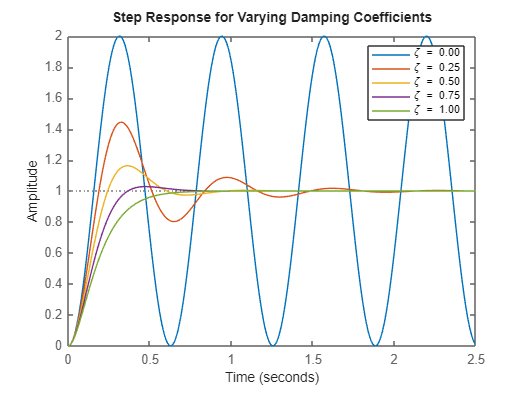

% Damping coefficients
zeta_vals = linspace(0, 1, 5);
t = 0:0.01:2.5;

figure;
hold on; grid on;

for i = 1:length(zeta_vals)
    z = zeta_vals(i);
    den = [1 2*z*omega_n omega_n^2];
    G = tf(num, den);
    step(G,t);
end

title('Step Response for Varying Damping Coefficients');
xlabel('Time');
ylabel('Amplitude');
legend(arrayfun(@(z) sprintf('\\zeta = %.2f', z), zeta_vals, 'UniformOutput', false));